# TEMPOmap 16Gene

run_id = 'test';

addpath('Z:/Documents/starmap_colab/Pipeline/');
addpath('Z:/Documents/starmap_colab/Code/matlab/');
addpath('Z:/Documents/starmap_colab/Code/matlab/myfunction/');

input_path = 'Z:/Data/Processed/2022-09-12-Rena-HeLa16Gene/';
% x, y, z, channel, round       
input_dim = [2048 2048 35 4 3]; 
gpu_block = [1024 1024 35 4 3]; 
% f_tile_range = {1:49}; 

% datasets = struct('input_path', f_paths, 'input_dim', f_dims, 'gpu_block', f_gblock);

useGPU = true;
% d = gpuDevice(1); 

data_dirs = dir(fullfile(input_path, "round1", "Position*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);

Ndirs = numel(data_dirs);
upd = textprogressbar(Ndirs, 'updatestep', 1);

Completed [                    ]   0% --:--:--

curr_out_path = 'Z:\Data\Processed\2022-09-12-Rena-HeLa16Gene\output\test\Position001'

Pipeline Obj is generated...


====Loading raw images====
Loading round 1...[time = 32.04 s]
Loading round 2...[time = 28.06 s]
Loading round 3...[time = 27.96 s]
Raw image as 5-D array


====Swap Channels====
Channel 2 <==> Channel 3


====Histogram Equalization====
Method: inter_round
Equalizing channel 1
Equalizing channel 2
Equalizing channel 3
Equalizing channel 4


====Histogram Equalization====
Method: intra_round
Equalizing round 1
Equalizing round 2
Equalizing round 3


====Morphological Reconstruction====
Method: 2d
Processing Round 1...[time = 3.43 s]
Processing Round 2...[time = 2.53 s]
Processing Round 3...[time = 2.40 s]


====Global Registration====
Round 2 vs. Round 1 finished [time=14.677406]
Shifted by -22   3  -1
Round 3 vs. Round 1 finished [time=14.586467]
Shifted by -16   4  -4


NgpuBlock = 4

gpu_idx = 2×2 int16 matrix
      1   1024
      1   1024


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 29.47 s]
Round 3 vs. Round 1...[time = 28.34 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 1
Number of spots found by max3d: 1833
[time = 27.14 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
27 
Decoding...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).

Number of spots were dropped because of multi-max color: 27


====Reads Filtration====
mode: regular
Base in both ends: C --- C
1.000000 [1806 / 1806] percent of reads are below score thresh 5.000000e-01
Filtration Statistics:
0.688261 [1243 / 1806] percent of good reads are CNNNNNC
0.688261 [1243 / 1806] percent of good reads are in codebook
1.000000 [1243 / 1243] percent of CNNNNNC reads are in codebook


block_offsets = 1×3 int16 row vector
   0   0   0


block_offsets = 1×3 int16 row vector
   0   0   0


====Block 1 Finished [time=105.058510]====

gpu_idx = 2×2 int16 matrix
      1   1024
   1025   2048


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 27.74 s]
Round 3 vs. Round 1...[time = 27.97 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 1
Number of spots found by max3d: 3770
[time = 26.47 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
14 
Decoding...

Number of spots were dropped because of multi-max color: 14


====Reads Filtration====
mode: regular
Base in both ends: C --- C
1.000000 [3756 / 3756] percent of reads are below score thresh 5.000000e-01
Filtration Statistics:
0.690362 [2593 / 3756] percent of good reads are CNNNNNC
0.690362 [2593 / 3756] percent of good reads are in codebook
1.000000 [2593 / 2593] percent of CNNNNNC reads are in codebook


block_offsets = 1×3 int16 row vector
   1024      0      0


block_offsets = 1×3 int16 row vector
   1024      0      0


====Block 2 Finished [time=84.427956]====

gpu_idx = 2×2 int16 matrix
   1025   2048
      1   1024


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 28.21 s]
Round 3 vs. Round 1...[time = 28.05 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 1
Number of spots found by max3d: 3402
[time = 27.79 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
41 
Decoding...

Number of spots were dropped because of multi-max color: 41


====Reads Filtration====
mode: regular
Base in both ends: C --- C
1.000000 [3361 / 3361] percent of reads are below score thresh 5.000000e-01
Filtration Statistics:
0.719131 [2417 / 3361] percent of good reads are CNNNNNC
0.719131 [2417 / 3361] percent of good reads are in codebook
1.000000 [2417 / 2417] percent of CNNNNNC reads are in codebook


block_offsets = 1×3 int16 row vector
      0   1024      0


block_offsets = 1×3 int16 row vector
      0   1024      0


====Block 3 Finished [time=85.900197]====

gpu_idx = 2×2 int16 matrix
   1025   2048
   1025   2048


Pipeline Obj is generated...


====Local (Non-rigid) Registration====
[time = 0.00 s]
Round 2 vs. Round 1...[time = 28.10 s]
Round 3 vs. Round 1...[time = 28.23 s]


====Load Codebook====
doReverse: 1


====Spot Finding====
Method: max3d
Reference round: 1
Number of spots found by max3d: 4964
[time = 26.96 s]


====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
61 
Decoding...

Number of spots were dropped because of multi-max color: 61


====Reads Filtration====
mode: regular
Base in both ends: C --- C
1.000000 [4903 / 4903] percent of reads are below score thresh 5.000000e-01
Filtration Statistics:
0.689782 [3382 / 4903] percent of good reads are CNNNNNC
0.689782 [3382 / 4903] percent of good reads are in codebook
1.000000 [3382 / 3382] percent of CNNNNNC reads are in codebook


block_offsets = 1×3 int16 row vector
   1024   1024      0


block_offsets = 1×3 int16 row vector
   1024   1024      0


====Block 4 Finished [time=85.591907]====

curr_img_out_path = 'Z:\Data\Processed\2022-09-12-Rena-HeLa16Gene\output\test\dots_image'

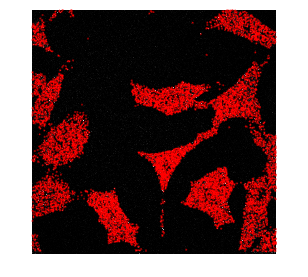

Completed [                    ]   0% 42:04:49

    
starting = tic;
for p=1:1
% for p=1:Ndirs % remove    
    curr_data_dir = data_dirs{p}; 
    curr_out_path = fullfile(input_path, 'output', run_id, curr_data_dir)
    
    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
                
    sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
    sdata.log = fopen(fullfile(curr_out_path, 'log.txt'), 'w');
    fprintf(sdata.log, sprintf("====Current Tile: %s====\n", curr_data_dir));
    sdata = sdata.LoadRawImages('sub_dir', curr_data_dir, 'input_dim', input_dim);
    sdata = sdata.SwapChannels; % !!
    %% TO ADD: min-max (ref. immune res)
      
    sdata = sdata.HistEqualize('Method', "inter_round");
    sdata = sdata.HistEqualize('Method', "intra_round");
    sdata = sdata.MorphoRecon('Method', "2d", 'radius', 3); % param-to-tune: radius
    
    sdata = sdata.test_GlobalRegistration;

    gpu_overlap = 0;
    gb_idx = BlockTest(sdata.rawImages, gpu_block, gpu_overlap);
    NgpuBlock = numel(gb_idx)
    
    tile_goodSpots = [];
    tile_goodReads = [];
    
    tile_allSpots = [];
    tile_allReads = [];
    
    tile_score = [];
    tile_counts = 0;
    
    for i=1:NgpuBlock
        
        bdata_start = tic;
        gpu_idx = gb_idx{i}
        
        fprintf(sdata.log, sprintf("====Current Block: %d====\n", i));
        fprintf(sdata.log, sprintf("Index: %d - %d - %d - %d\n", gpu_idx));
        
        bdata = new_STARMapDataset(input_path, 'useGPU', useGPU);
        bdata.log = sdata.log;
        bdata = bdata.LoadDim(gpu_block);
        bdata.registeredImages = gpuArray(sdata.registeredImages(...
            gpu_idx(1,1):gpu_idx(1,2),...
            gpu_idx(2,1):gpu_idx(2,2),...
            :,:,:));
        
        bdata = bdata.LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 1);
         
        % replace the old image 
        sdata.registeredImages(...
            gpu_idx(1,1):gpu_idx(1,2),...
            gpu_idx(2,1):gpu_idx(2,2),...
            :,:,:) = bdata.registeredImages;
        
        bdata = bdata.LoadCodebook;
        bdata = bdata.SpotFinding('Method', "max3d", 'ref_index', 1, 'showPlots', false);
        bdata = bdata.ReadsExtraction('voxelSize', [2 2 1]); 
        bdata = bdata.ReadsFiltration('showPlots', false);
        
        % block_offsets = [gpu_idx(2,1) - 1 gpu_idx(1,1) - 1 0]
        if size(bdata.goodSpots, 1) ~= 0
            block_offsets = [gpu_idx(2,1) - 1 gpu_idx(1,1) - 1 0]
            block_offsets = repmat(block_offsets, size(bdata.goodSpots, 1), 1);
            bdata.goodSpots = bdata.goodSpots + int16(block_offsets);
            
            block_offsets = [gpu_idx(2,1) - 1 gpu_idx(1,1) - 1 0]
            block_offsets = repmat(block_offsets, size(bdata.allSpots, 1), 1);
            bdata.allSpots = bdata.allSpots + int16(block_offsets);
        end
        
        % Update tile reads
        tile_goodSpots = [tile_goodSpots; bdata.goodSpots];
        tile_goodReads = [tile_goodReads; bdata.goodReads];
        
        tile_allSpots = [tile_allSpots; bdata.allSpots];
        tile_allReads = [tile_allReads; bdata.allReads];
        
        tile_score = [tile_score; bdata.FilterScores];
        tile_counts = tile_counts + size(bdata.allSpots, 1);
        
        fprintf(sprintf("====Block %d Finished [time=%02f]====", i, toc(bdata_start)));
    end
    
    % Save round 1 image
    output_dir = fullfile(input_path, 'output', run_id, 'round1_merged');
    if ~exist(output_dir, 'dir')
       mkdir(output_dir);
    end
    r1_img = max(sdata.registeredImages(:,:,:,:,1), [], 4);
    r1_img_name = fullfile(output_dir, sprintf("%s.tif", curr_data_dir));
    SaveSingleTiff(r1_img, r1_img_name)
    
%         % Save registered image
%         output_dir = fullfile(curr_out_path, 'registered_image');
%         if ~exist(output_dir, 'dir')
%            mkdir(output_dir);
%         end
%         new_SaveImg(output_dir, sdata.registeredImages);
    
%         % Save cell image
%         output_dir = fullfile(input_path, 'output', run_id);
%         if ~exist(output_dir, 'dir')
%            mkdir(output_dir);
%         end
%         sub_dirs = ["dapi", "ER", "ch03", "actb"];
%         SaveCellImg(output_dir, sdata.proteinImages, curr_data_dir, sub_dirs);
    
    % Save tile points 
    save(fullfile(curr_out_path, strcat('goodPoints_max3d.mat')), 'tile_goodReads', 'tile_goodSpots');
    save(fullfile(curr_out_path, strcat('allPoints_max3d.mat')), 'tile_allReads', 'tile_allSpots');
    
    fprintf(sdata.log, sprintf("Average Score: %.2f - %.2f - %.2f\n", mean(tile_score, 'omitnan')));
    
    % Save dots image 
    curr_img = max(sdata.registeredImages(:,:,:,:,1), [], 4);
    curr_img = max(curr_img, [], 3);
    
    curr_img_out_path = fullfile(input_path, 'output', run_id, 'dots_image')

    if ~exist(curr_img_out_path, 'dir')
        mkdir(curr_img_out_path)
    end

    if ~isempty(tile_goodSpots)
        plot_centroids(tile_goodSpots, curr_img, 2, 'r')
        saveas(gcf, fullfile(curr_img_out_path, sprintf("%s.tif", curr_data_dir)));
    end

    reset(gpuDevice)
    
    fclose(sdata.log);
    upd(p);
end


sdata.jobFinished

ans = struct with fields:
                  LoadRawImages: 'uint8'
                   SwapChannels: [1 2 3]
          HistogramEqualization: "rawImages"
    MorphologicalReconstruction: 1
        test_GlobalRegistration: 1




toc(starting) / 3600

ans = 0.1436

## Plot spot on dapi

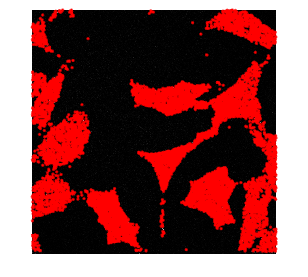

% curr_dapi = fullfile(input_path, 'dapi', curr_data_dir);
% curr_dapi = dir(fullfile(curr_dapi, "*.tif"));
% curr_dapi = new_LoadMultipageTiff(fullfile(curr_dapi(1).folder, curr_dapi(1).name), 'uint8', 'uint8', false);
% curr_dapi = max(sdata.registeredImages(:,:,:,:,1), [], 4);
% 
% curr_dapi = max(curr_dapi, [], 3);

curr_dapi = max(sdata.registeredImages(:,:,:,:,1), [], 4);
curr_dapi = max(curr_dapi, [], 3);
plot_centroids(tile_goodSpots, curr_dapi, 5, 'r')

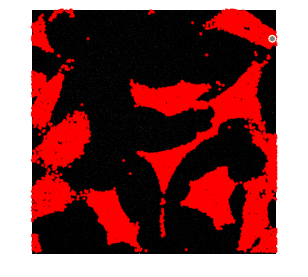

plot_centroids(tile_allSpots, curr_dapi, 5, 'r')

% saveas(gcf, fullfile(curr_img_out_path, sprintf("%s.tif", curr_data_dir)));